Vezmeme si BGD s adaptivním moomentem a doděláme to něj způsob, jak najít ideální bázové funkce pro regresi. Použijeme k tomu velkou bázovou funkci s celou řadou různých funkcí (dělčky, násobičky, síny, cosíny atd..), kde všude bude jiný parametr. Poté tzv. Lasso Regression potlačí parametry, které jsou malé (a nejsou tudíž úplně potřeba). To znamená že výpočtem získáme model jen s omezeným počtem parametrů bázových funkcí (rychlejší na výpočet) ale s dobrým proložením. 

Testovací data budou v podobě zašuměnné:

#### 
$$y\left(x\right)=\frac{\sin \left(\pi x\right)}{x^2 +1}$$
 

Bázová funkce našeho modelu vzniká podle slovníku:

#### 
$$\begin{array}{l}
u_1 \;=w\;\textrm{id}\left(x\right)+b\\
u_2 =\sin \left(w\;x+b\right)\\
v_1 =\left(w_1 x_1 \right)*\left(b_1 x_2 \right)\\
v_1 =\frac{\left(w_1 x_1 +b_1 \right)}{\left(w_2 x_2 +b_2 \right)}
\end{array}$$


func = @(x) (sin(pi.*x))./((x.^2)+1);    % funkce pro nagenerování dat
from = 0;                           % rozsah pro od ...
to = 2;                             % ... do pro nagenerování dat
N =  200;                           % počet vzorků
x = from:((to-from)/(N-1)):to;      % vzorkovací čas
% y = awgn(func(x),27);               % generátor naměřených dat skrze funkci pro nagenerování dat (prostě přidá do funkce šum)
y = [0.0298656896269880,0.109766267733079,0.0668915048063826,0.106242368512189,0.0553855266575713,0.136255455637044,0.120915002380381,0.211532557167483,0.213489888308874,0.220543792656902,0.307212583039145,0.298708856008389,0.421212107321877,0.491826887234687,0.426292710191314,0.458571977069784,0.384290634095908,0.563732226463622,0.493302664205136,0.562160692062685,0.558419898406971,0.604620757541701,0.606402946684143,0.636187476998177,0.601985460780460,0.673665174689248,0.618516681545710,0.696434849592990,0.724733587034512,0.718429769108826,0.758693316765038,0.795930406851633,0.696425741317914,0.712815242840448,0.759303134503403,0.814245396954751,0.817659350900348,0.792416591294165,0.839251021914612,0.910228739718005,0.772202665540853,0.784641849579925,0.741741604757703,0.829532046291192,0.858190115883340,0.804278778533424,0.866827425547599,0.804154073156698,0.820861170004116,0.849879449472163,0.824627400265009,0.805425233345341,0.847206331064188,0.734052727508256,0.744772424765463,0.768693613504914,0.728752543113144,0.708086838015578,0.753385276376785,0.685854154684301,0.712915116748795,0.673261125364717,0.647642002510720,0.672691223657397,0.649956893892889,0.533037528908273,0.589887098044540,0.540299731326985,0.576568450357544,0.522284203130816,0.536160871382652,0.574976517753167,0.576937787500597,0.518316180347972,0.392792018029058,0.511079788119527,0.474789071633636,0.419198359388005,0.497463520649676,0.349263744982504,0.430888742054047,0.282238661753092,0.294821835554650,0.241118189707444,0.299603183484017,0.271776960288092,0.207570333680997,0.155061732956790,0.0787905811143228,0.138220309686523,0.0984341748694308,0.173921178038289,0.174598961130783,0.0193361376500105,0.0132464698355674,0.0526828751431539,0.0994315057849897,0.0964076328063964,0.0897146608901084,-0.00977322840781223,-0.0372280816082464,-0.0694935231041728,-0.0138389647144669,-0.0190738712887916,-0.136021570658266,-0.0879943717310612,-0.119189119282237,-0.0818915883885270,-0.0706438446704520,-0.0807215505381541,-0.124694977547944,-0.176943726597961,-0.190943184094421,-0.233022527679767,-0.139106858025517,-0.241380830938702,-0.297957996222008,-0.257218204476684,-0.164345477820191,-0.226333477880537,-0.262054924047882,-0.244172280616659,-0.243153126693265,-0.247729390155447,-0.281715240912670,-0.177576136843003,-0.237889992730323,-0.400931946160603,-0.337512333743319,-0.300784472489889,-0.281042889141176,-0.319491196933704,-0.311948518475171,-0.327152968111840,-0.373795718490723,-0.221840860143418,-0.327339383609387,-0.215978132858970,-0.360457966431711,-0.332702789734994,-0.379851195399521,-0.359436294837872,-0.280420431144353,-0.286120919679368,-0.357831133770876,-0.310513743282909,-0.335153944756948,-0.276439267956310,-0.345409076302786,-0.238903425339107,-0.374726896607612,-0.289299187537738,-0.366423237018793,-0.327555052782864,-0.339247609602293,-0.217846160871059,-0.289891484989649,-0.263464583889273,-0.337605176873605,-0.311062704461895,-0.247442162385605,-0.262182764776867,-0.222503426343881,-0.194598706332143,-0.281469468969149,-0.277724038535006,-0.207831776401144,-0.227304974536567,-0.214915022340555,-0.248518723519916,-0.244701134849419,-0.175644036652768,-0.119098158896320,-0.197372963473924,-0.125431787453975,-0.106724458181618,-0.112944304114881,-0.0859684684031971,-0.130515732838651,-0.211454805018047,-0.168930413626429,-0.131807703058645,-0.182522134726495,-0.133843193263616,-0.0462579712271313,-0.130841728587720,-0.0797160375534842,-0.0690494826200434,0.00794482491482185,-0.0786339318703164,-0.0315113031797069,-0.108347157957052,-0.0855909002450379,-0.0249546523631807,-0.00932057617189958,-0.0471113206743972,-0.00710797105951257,-0.0428761768992976,0.0192860104851071,-0.0313727140496005];

Koeficient $\alpha$ je klasicky koeficient učení a koeficient $\tau$ zase maximální přípustnou chybu v modelu.

alpha = 100e-3;   % míra učení 
tau = 3*1e-1;     % maximální možná chyba pro ukončení výpočtu

Koeficient $\lambda$ zase vyjadřuje, jak moc budou malé koeficienty tlumené. Pokud bude $\lambda$ hodně velké, tak utlumí všechny koeficienty a aproximace bude velmi špatná. Pokud bude naopak příliš malé, tak se v řešeení nijak neprojeví. Pokud ale nastavíme tento koeficient na rozumnou hodnotu, tak můžeme docílit stále kvalitně aproximujícího modelu, který ale bude mít určité koeficienty téměř nulové. To znamená, že je můžeme z modelu vypusitit a tím zrychlit následný výpočet.

lambda = 1e-3; % koeficient regularizace pro malé koeficienty.

Naše bázová funkce má tedy podobu podle slovníku výše. Následující kód generuje právě tuto funkci vytvoří:

syms x_sym;

number_of_coefficients = 9;
syms w_sym [1,number_of_coefficients]
syms b_sym [1,number_of_coefficients]

syms y_sym_1 [3,1]
y_sym_1(1) = sym(w_sym(1) .* x_sym + b_sym(1));
y_sym_1(2) = sym(sin(w_sym(2) .* x_sym + b_sym(2)));
y_sym_1(3) = sym((w_sym(3) .* x_sym).*(b_sym(3) .* x_sym));

syms x1_sym;
syms x2_sym;
syms sym_w1;
syms sym_b1;
syms sym_w2;
syms sym_b2;


yd = sym(((sym_w1 .* x1_sym)+sym_b1)./((sym_w2 .* x2_sym)+sym_b2));

syms y_sym1 [1,9]

for i = 1:3
    for j = 1:3
        
        counter = ((i-1)*3)+j;
       
        y_sym1(counter) = subs(yd,sym_w1,w_sym(i+3));
        y_sym1(counter) = subs(y_sym1(counter),sym_b1,b_sym(i+3));
        y_sym1(counter) = subs(y_sym1(counter),sym_w2,w_sym(j+6));
        y_sym1(counter) = subs(y_sym1(counter),sym_b2,b_sym(j+6));
        
        y_sym1(counter) = subs(y_sym1(counter),x1_sym,y_sym_1(i));
        y_sym1(counter) = subs(y_sym1(counter),x2_sym,y_sym_1(j));
        
        
    end
end

y_sym = sum(y_sym1); 

Aby byl vliv Lasso regularizace patrný, tak vypočteme jeden a ten samý příklad několikrát pro různé hodnoty regularizace a porovnáme je mezi sebou. Z toho důvodu si předpřipravíme vše co je možné, aby následný výpočet trval co nejkratší dobu. Takže zde je připraven výpočet pro ztrátovou funkci a koeficienty pro výpočet adaptivního momentu.

model = subs(y_sym,x_sym,x);
epsilon = 10e-8;
beta1 = 0.9;
beta2 = 0.999;

Tato proměná počítá kolikrát byl výpočet pro různé hodnoty regularizace proveden.

counter = 1;

Tato proměná zase vypovídá o tom, jaké hodnoty regularizace budou počítány

% range = -3:0.05:1;

A nyní už výpočet. Ten začíná výjádřením ztrátové funkce podle vzorce metody nejmenších čtverců s Lasso regularizací:

#### 
$$E=\left(\sum_{n_0 }^N {\left(y_{naměřené} -y_{aproximovaé} \right)}^2 \right)+\lambda \left(|w_1 |+|w_2 |+|w_3 |+\ldotp \ldotp \ldotp +|w_m |\right)$$


kde vzorec metody nejmenších čtverců je klasický, ale je zde připočítávána absolutní hodnota všech koeficientů přenásobená koeficientem $\lambda$.  Následuje už pouze výpočet gradientu, nastavení počátečních koeficientů a samotný výpočet za pomocí ADAMa.

% for j = range
%    
%     lambda = (0.1^-j); %     lambda = (0.1^-0.5);
%     lasso = lambda.*(sum(abs([w_sym b_sym])));
%     E_sym = sum(((y-model).^2) + lasso); %     E_sym = sum(((y-model).^2));
%     
%     grad_E_sym = gradient(E_sym,[w_sym,b_sym]);
%     
%     m = 0;
%     v = 0;
% 
%     w = [2;0.3;-0.2;0.5;1;0.7;0.1;1.2];  % w = (4.*rand(number_of_coefficients,1)-2); % náhodné koeficienty v rozmezí -2 až 2... %     w = (ones(number_of_coefficients,1));
%     b = [1.5;0;0.2;0.1;-0.5;0.2];
%     
%     koef = [w;b];
%     iter = 300;
%     
%     for i = 1:iter 
%    
%         grad_E = double(subs(grad_E_sym,[w_sym b_sym],koef'));
%         
%         m = beta1.*m+(1-beta1).*grad_E;
%         v = beta2.*v+(1-beta2).*grad_E.^2;
%  
%         mm = m./(1-beta1^i);
%         vv = v./(1-beta2^i);
%        
%         if (abs(max(grad_E)) < tau)
%             iter = i;
%             break;
%         end
% 
%         koef = koef - ((alpha.*mm)./(sqrt(vv)+epsilon));
%             
% %         w = koef(1:8)
% %         b = koef(9:14)
% % %         y_model = double(subs(subs(y_sym,w_sym,w'),x_sym,x));
% %         y_model = double(subs(subs(y_sym,[w_sym b_sym],koef'),x_sym,x));        
% %         plot(x,y_model);
% %         drawnow;
%     
%     end

Po nalezení koeficietů jsou koeficienty vypsány, a uloženy do matice pro pozdější vykreslení. 

%     w = koef(1:8)
%     b = koef(9:14)
%     iter
%     KOEF(:,counter) = koef;


Zde jsou vpočteny body podle aproximace, a to z důvodu, abychom mohli vypočíst pomocí metody nejměnších čtverců jejich odchylku od naměřených dat. Tyto odchylky ukládám do matice mse (mean square error) pro pozdější vykreslení.

Následuje vykreslení naměřených dat.

plot(x,y,"ro");
hold on;

for i = range
    
    koef = KOEF(:,counter);
    
    y_model = double(subs(subs(y_sym,[w_sym b_sym],koef'),x_sym,x)); 
    mse(counter) = Least_squares_method(y,y_model);

Vykreslení aproximace vypočteným modelem.

    plot(x,y_model);
    hold on;

Je inkrementován čítač a výpočet běží pro další hodnotu $\lambda$.

    counter = counter + 1; 
end

Vypočtené výsledky můžeme zobrazit takto: 

První gaf ukazuje, že čím větší Lasso regulatizaci jsme zavedli, tím víc nám utlumovala i koeficienty (v našem případě jen koeficient $w_4$), které utlumeny být neměly. V důsledku toho je pro velkou regularizaci model výrazně hoorší. Naoopak pro malé hodnoty $\lambda$ je vidět, že nám výslednou hodnotu ztrátové funkce spočtenou metodou nejmenších čtverců už prakticky nemění. 

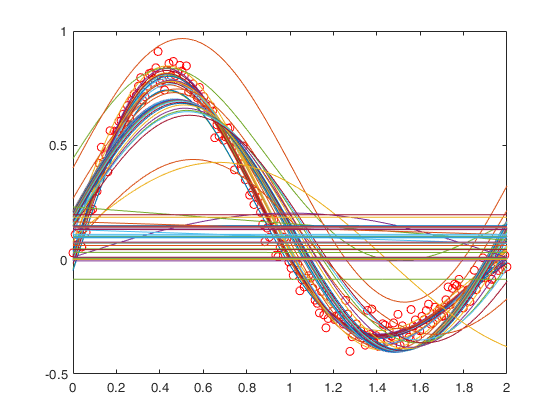

hold off;

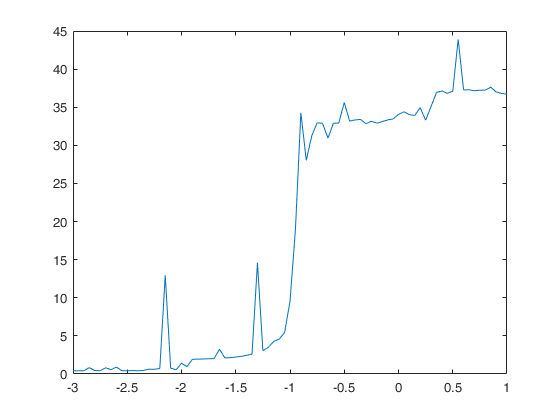

plot(range,mse);
hold off;

Druhý graf zobrazuje jakou měli koeficienty hodnotu napříč všemi výpočty. Lze vidět, že pro malé hodnoty $\lambda$ byli všechny koeficienty nenulové, ale ty nejmenší byli následně tlumeny až do zanedbatelné velikosti. Zároveň je ale vidět, že pro velké $\lambda$ nám regularizace utlumila všechny koeficienty, čili i koeficient $w_4$, který byl pro aproximaci stěžejní. 

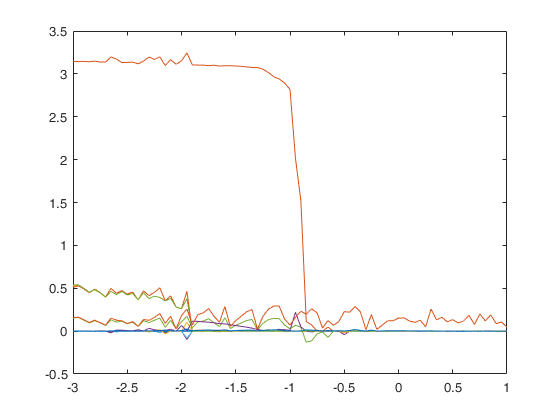

for i = 1:number_of_coefficients*2-3
    plot(range,KOEF(i,:));
    hold on
end
plot(range,KOEF(18,:));
hold off

Nakonec si vykreslíme Paretovo optimum závislosti počtu nenulových koeficientů v modelu ku hodnotě nejmenších čtverců. Pro tento účel vytvoříme vektor noc (number of coefficients), který naplníme podle toho, kolik koeficientů bylo při dané hodnotě lasso regularizace nenulových. Hodnota nejmenších čtverců odpovídá hodnotám grafu výše. Barvou je vyjádřena hodnota koeficientu $\lambda$.

noc = zeros(1,(counter-1));
for i = 1:counter-1
    for j = 1:number_of_coefficients*2
        if (KOEF(j,i)>0.0007) % 0.0007 je můj určený trashold pro nulový koeficiet v tomto případě
            noc(i) = noc(i) + 1; 
        end
    end    
end
scatter(mse,noc,50,range,'filled')
colorbar

Podíváme se jak vypadá extrapolace naším modelem:

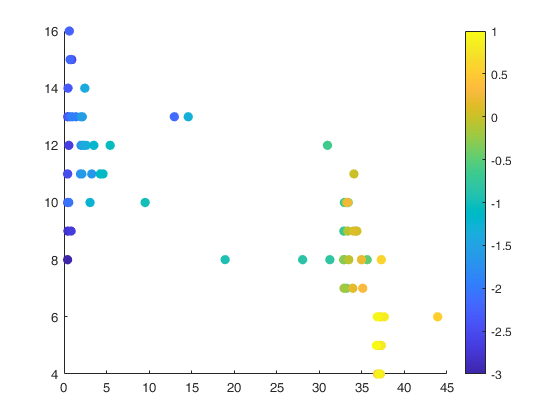

x = -6:0.01:6;
y_model = double(subs(subs(y_sym,[w_sym b_sym],KOEF(:,13)'),x_sym,x)); % lambda = -2,4

hold off;

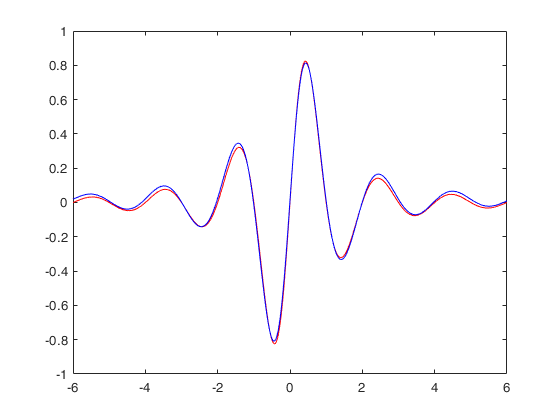

plot(x,func(x),"r-");
hold on;
plot(x,y_model,"b-");